# Prerequisites

Alex Cerjanic (acerj@udel.edu)

Welcome, dear reader! These interactive documents will attempt to give you a gentle, but thorough introduction to the fundamentals of iterative MRI reconstruction as used in non-Carteisan applications, such as spiral imaging. This time, we will focus on the nuts-and-bolts basics we need for our discussions going forward. Some of this discussion will center on developing our shared vocabulary in words and in mathematics. 

Please note MNL lab members: This section will be updated as we progress with the journal club to include useful math and notation. Please check back for updates.

**Learning Objectives:**

- Describe common terminology as used in MRI reconstruction

- Describe common variables and notation used in MRI reconstruction

- Review basic mathematics commonly used in MRI reconstruction, such as matrix algebra, optimization, and complex phasors.

## Estabishing a common vocabulary

- Object ($x$) - The physical object being imaged via MRI. Often, this object is an unknowable quantity that we are trying to approximate via the imaging process.

- k-space data (or often just 'data') ($y$) - The samples obtained from the imaging process that correspond to the k-space representation of the object.

- Object estimate ($\left.\hat{x} \right)$- This is our estimate of the object, usually after solving our image reconstruction problem. The hat ($\hat{}$) notation is borrowed from estimation theory to distinguish the (often unknowable) ground truth from the (all-too-often) imperfect achievable estimate.

## Image reconstruction as an application of row vector-column vector and matrix-vector operations

When we start working with image reconstruction problems, we will often formulate reconstruction problems in terms of matrix-vector operations. We do this not to bring back bad memories of learning matrix multiplications or finding determinants by hand, but to simplify how we notate the problems, and organize how we think about, and implement solutions to reconstruction problems via computer.

We will start simply, by reminding ourselves that any 2D or 3D (or 4D or 5D and so on) image can be represented by a single 1D column vector. Starting with a 2D array representation of an image, we can certainly visualize it.

x = phantom('Modified Shepp-Logan',64); % Generate a 64x64 image
size(x)

ans =     64    64


im(x), colormap(gray), drawnow

And just to prove it to ourselves, we can reshape the 2D array into a 1D array. We use the handy "col" function from the MIRT for this function. The text of the function is provided for your reference.

% function x = col(x)
% %function x = col(x)
% %	"colon" function
% x = x(:);
% %x = reshape(x,[],1);

x = col(x);
size(x)

ans =         4096           1


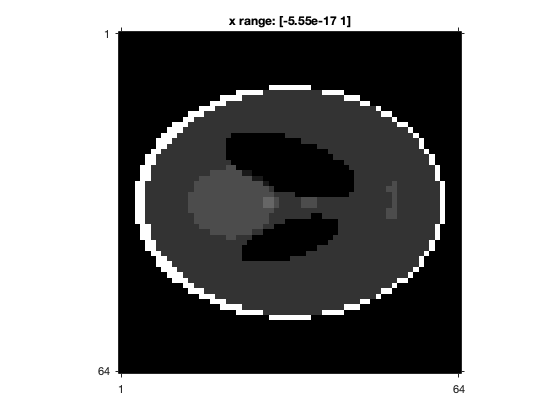

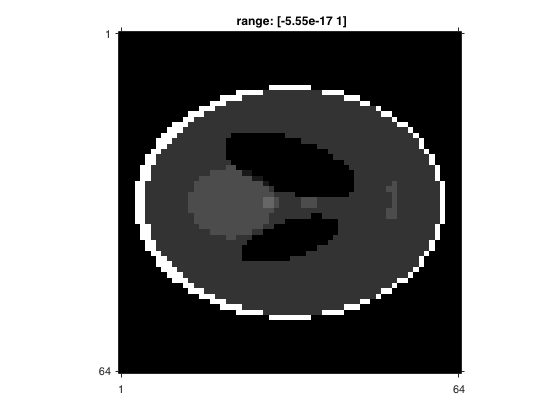

im(reshape(x, [64,64]))

Likewise, we often will represent summations at row-vector column multiplications.  Below is an example of this kind of notation.


$$y=\sum_{i=1}^N a_i \;x_i \;=a_1 x_1 +a_2 x_2 +a_3 x_3 +\cdots +a_N x_N =\left\lbrack \begin{array}{ccccc}
a_1  & a_2  & a_3  & \cdots  & a_N 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
\vdots \\
x_N 
\end{array}\right\rbrack =a^T x$$


This both for notational purposes (look how much more compact the right is compared to the left, dear reader!), as well as computational reasons. Let's see a reason why we might want to do this in MATLAB code below:

a = col(0:.01:100); % Generate a column vector of floating point numbers
x = col(0:.01:100); % Generate a column vector of floating point numbers.

%  Implement the summation naively
tic
y = 0;
for ii=1:length(a)
    y = y + a(ii) * x(ii);
end
disp(y)

   3.3338e+07



toc

Elapsed time is 0.026268 seconds.


% Implement the summation as a row vector operation
tic
y = a'*x;
disp(y)

   3.3338e+07



toc

Elapsed time is 0.006047 seconds.


So, dear reader, what happened? We got the same answer both ways, but the summation required 4 lines of code and a for loop to implement. It was also almost 4 times slower than the one line row-vector operation. Neat!

## Until Next Time! 